# EEE 321 - Signals and Systems - Lab 2 - Tuna Şahin 22201730

## Convolution Calculation and Plotting

Generate the h[n] impulse response function given as:    $h\left\lbrack n\right\rbrack ={\left(\frac{\;7}{8}\right)}^n u\left\lbrack n-4\right\rbrack$

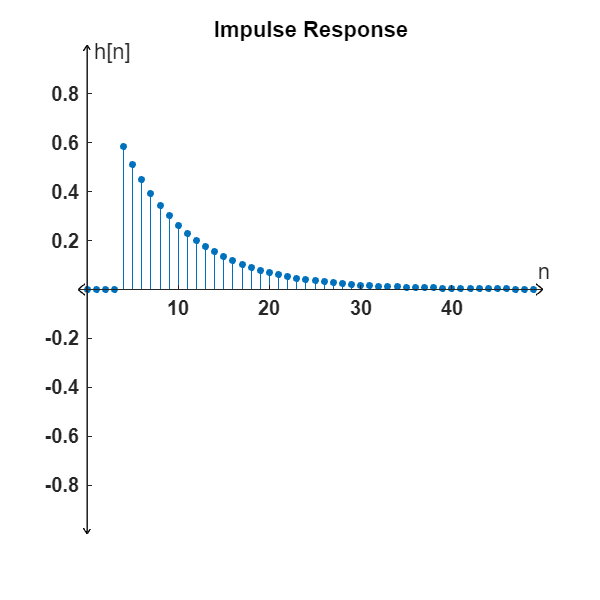

n = linspace(-100,100,201);
h = (7/8).^(n).*arrayfun(@u,n-4);
finestem(n,h,'Impulse Response','n','h[n]',[-1 50],[-1 1],'off',[400 400]);

We can see that $h\left\lbrack n\right\rbrack <0,\forall \;n<0$ so we can confirm that this system is causal. To check for stability we can calculate the following sum: $\sum_{-\infty}^{\infty}\left(\frac78\right)^nu[n] =
\sum_{0}^{\infty}\left(\frac78\right)^n =
\frac1{1-\frac78}=
8$ which is finite therefore the system is stable.

##     Question 1:

Analytical Calculation: 


$$y\left\lbrack n\right\rbrack =$$

$$$
\[
    \begin{cases}
      0 & n\leq 4 \\
      3\sum_{i=4} ^{n} (\frac{7}{8})^{n-4}  & 4\leq n\leq 12 \\
      n[12].(\frac{7}{8})^{n-12} & 12 >n
    \end{cases}
\end{cases}
\]
$$$


We can simply observe the result of this convolution. Firstly we will shift the rectangular area of $x_1$starting from the left. The rectangle will act as an acumulator for the first 9 values. After that, all the values in the rectangular area will decay with a multiplier of $\frac{7}{8}$. We can then write the remaining area of $n>12\;$as we have.

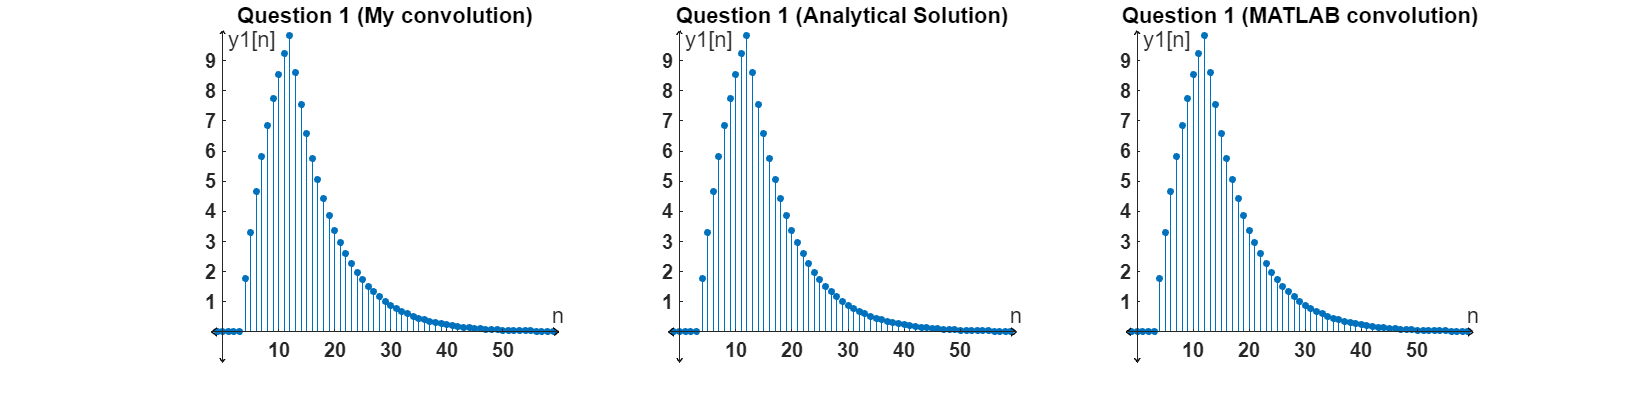

x1 = [3 3 3 3 3 3 3 3 3]; % we use zero padding for the rest of the functions
y1 = convolution(x1,h);
y1a = arrayfun(@q1,n); % mapping the analytical solution to an array
n = linspace(-100,length(y1)-101,length(y1));

subplot(1,3,1)
finestem(n,y1,'Question 1 (My convolution)','n','y1[n]',[-2 60],[-1 10],'off',[1600 400])
subplot(1,3,2)
finestem(n,y1a,'Question 1 (Analytical Solution)','n','y1[n]',[-2 60],[-1 10],'off',[1600 400])
subplot(1,3,3)
finestem(n,conv(x1,h),'Question 1 (MATLAB convolution)','n','y1[n]',[-2 60],[-1 10],'off',[1600 400])

We can see all of the plots for this question are identical. Therefore, we can say that my analytical solution and my convolution functions were correct.

##     Question 2:

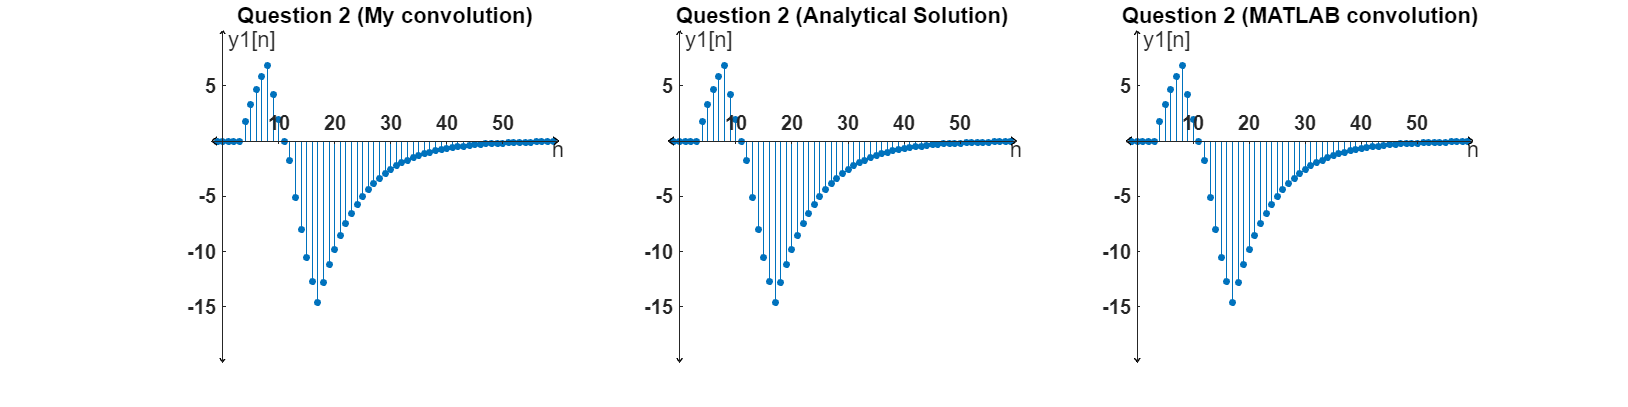

x2=[3 3 3 3 3 -3 -3 -3 -3 -6 -6 -6 -6 -6];
y2 = convolution(x2,h);
y2a = [y1a 0 0 0 0 0] - 2*[0 0 0 0 0 y1a]; %obtaining the analytical solution from the first question.
n = linspace(-100,length(y2)-101,length(y2));

subplot(1,3,1)
finestem(n,y2,'Question 2 (My convolution)','n','y1[n]',[-2 60],[-20 10],'off',[1600 400])
subplot(1,3,2)
finestem(n,y2a,'Question 2 (Analytical Solution)','n','y1[n]',[-2 60],[-20 10],'off',[1600 400])
subplot(1,3,3)
finestem(n,conv(x2,h),'Question 2 (MATLAB convolution)','n','y1[n]',[-2 60],[-20 10],'off',[1600 400])

We can see all of the plots for this question are identical. Therefore, we can say that my analytical solution and my convolution functions were correct.

##     Question 3:

Analytical solution:

$x_3 \left\lbrack n\right\rbrack =e^{\frac{\;\textrm{jn}}{3}} \ldotp u\left\lbrack n-2\right\rbrack \ldotp u\left\lbrack 20-n\right\rbrack$,    $h\left\lbrack n\right\rbrack ={\left(\frac{\;7}{8}\right)}^n u\left\lbrack n-4\right\rbrack$


$$y\left\lbrack n\right\rbrack =x_3 \left\lbrack n\right\rbrack *h\left\lbrack n\right\rbrack \;\;\;\;\;\;\;\;\Rightarrow \;\;\;\;\;\;\;\;\sum_{k=-\infty \;}^{\infty \;} {\left(\frac{\;7}{8}\right)}^n u\left\lbrack n-4\right\rbrack \ldotp e^{\frac{\;j\left(n-k\right)}{3}} \ldotp u\left\lbrack n-k-2\right\rbrack \ldotp u\left\lbrack 20-n+k\right\rbrack \;\;\;\;\;\;\;\;$$



$$\Rightarrow \;\;\;\;\;\;e^{\frac{\;\textrm{jn}}{3}} \sum_{k=4}^{\infty \;} {\left(\frac{\;7e^{\frac{\;-j}{3}} }{8}\right)}^n u\left\lbrack n-k-2\right\rbrack \ldotp u\left\lbrack 20-n+k\right\rbrack \;\;\;\;\;\;\;\;\Rightarrow \;\;$$
     
$$\;y\left\lbrack n\right\rbrack =\left\lbrace \begin{array}{ll}
\sum_{k=4}^{n-2} {\left(\frac{\;7e^{-\frac{j}{3}} }{8}\right)}^k  & n\le \;24\\
\sum_{k=\;n-20}^{n-2} {\left(\frac{\;7e^{-\frac{j}{3}} }{8}\right)}^k  & n>24
\end{array}\right\rbrace$$


We can write the second part recursively to clean it up and substituting the formula for the sum of geometric series we get the following expression:


$$y\left\lbrack n\right\rbrack =$$

$$$
\[
    \begin{cases}
      0 & n<6\\
       e^{\frac{jn}{3}}                 \sum_{i=4} ^{n-2} \frac{\left(\frac{7e^{\frac{-j}{3}}}{8}\right)^{4}- \left(\frac{7e^{\frac{-j}{3}}}{8}\right)^{n-1}}  {\left(1-\frac{7e^{\frac{-j}{3}}}{8}\right)}  & 6\leq n\leq 24 \\
      n[24].\left(\frac{7}{8}\right)^{n-24} & 24 >n
    \end{cases}
\end{cases}
\]
$$$
 

The decay with a multiplier of $\frac{\;7}{8}$ is again present. 

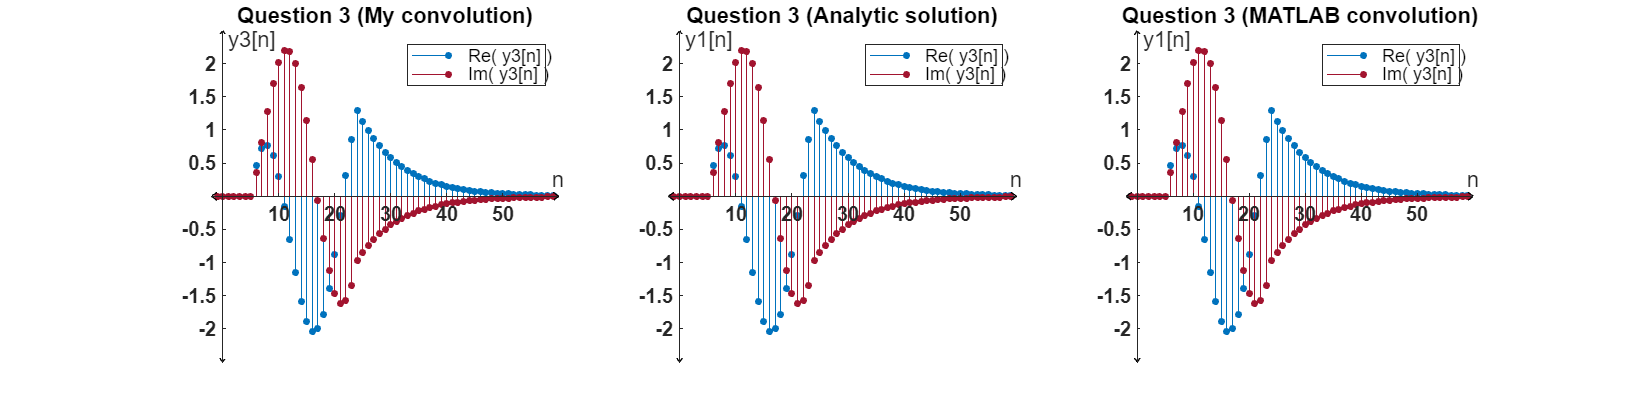

x3 = [0 0 exp(1i*(1/3)*linspace(2,20,19))];
y3 = convolution(x3,h);
y3a = arrayfun(@q3,n); % mapping the analytical solution to an array
n = linspace(-100,length(y3)-101,length(y3));

subplot(1,3,1)
finestem(n,real(y3),'Question 3 (My convolution)','n','y3[n]',[-2 60],[-2.5 2.5],'on',[1600 400])
finestem(n,imag(y3),'Question 3 (My convolution)','n','y3[n]',[-2 60],[-2.5 2.5],'off',[1600 400])
legend('Re( y3[n] )','','','','','','Im( y3[n] )') 
subplot(1,3,2)
finestem(n,real(y3a),'Question 3 (Analytic solution)','n','y1[n]',[-2 60],[-2.5 2.5],'on',[1600 400])
finestem(n,imag(y3a),'Question 3 (Analytic solution)','n','y1[n]',[-2 60],[-2.5 2.5],'off',[1600 400])
legend('Re( y3[n] )','','','','','','Im( y3[n] )')  
subplot(1,3,3)
finestem(n,real(conv(x3,h)),'Question 3 (MATLAB convolution)','n','y1[n]',[-2 60],[-2.5 2.5],'on',[1600 400])
finestem(n,imag(conv(x3,h)),'Question 3 (MATLAB convolution)','n','y1[n]',[-2 60],[-2.5 2.5],'off',[1600 400])
legend('Re( y3[n] )','','','','','','Im( y3[n] )')  

We can see all of the plots for this question are identical. Therefore, we can say that my analytical solution and my convolution functions were correct.

##     Question 4:

We know that $-3\sin \left(\frac{1}{3}n\right)=-3\textrm{Re}\left(e^{\frac{j}{3}n} \right)$ therefore we can just use the values for the analytical solution of Q3 and multiply their real part with -3 as:

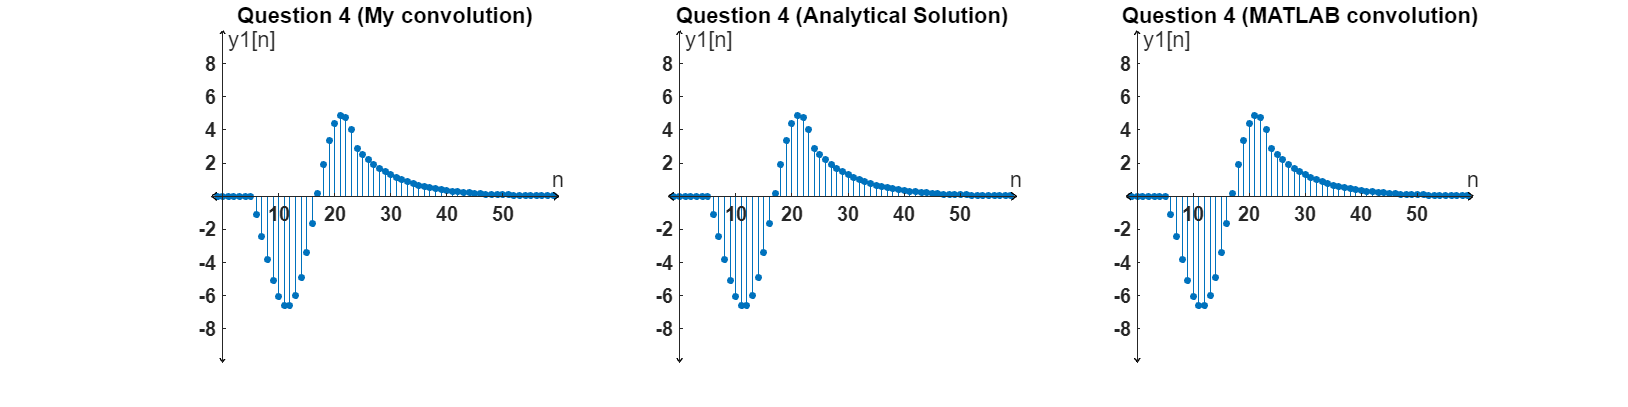

y4 = -3*imag(y3); 
y4a = -3*imag(y3a); 
subplot(1,3,1)
finestem(n,y4,'Question 4 (My convolution)','n','y1[n]',[-2 60],[-10 10],'off',[1600 400])
subplot(1,3,2)
finestem(n,y4a,'Question 4 (Analytical Solution)','n','y1[n]',[-2 60],[-10 10],'off',[1600 400])
subplot(1,3,3)
finestem(n,-3*imag(conv(x3,h)),'Question 4 (MATLAB convolution)','n','y1[n]',[-2 60],[-10 10],'off',[1600 400])

We can see all of the plots for this question are identical. Therefore, we can say that my analytical solution and my convolution functions were correct.

##     Question 5: 

We know that $2\cos \left(\frac{1}{3}n\right)=2\textrm{Im}\left(e^{\frac{j}{3}n} \right)$ therefore we can just use the values for the analytical solution of Q3 and multiply their imaginary part with 2 as:

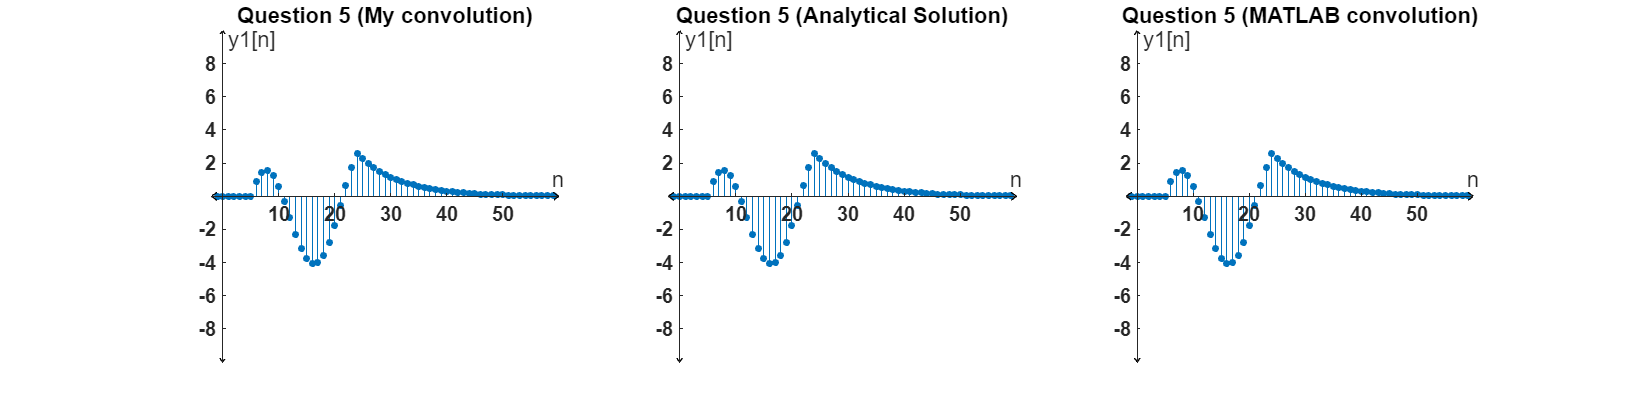

y5 = 2*real(y3);
y5a = 2*real(y3a);

subplot(1,3,1)
finestem(n,y5,'Question 5 (My convolution)','n','y1[n]',[-2 60],[-10 10],'off',[1600 400])
subplot(1,3,2)
finestem(n,y5a,'Question 5 (Analytical Solution)','n','y1[n]',[-2 60],[-10 10],'off',[1600 400])
subplot(1,3,3)
finestem(n,2*real(conv(x3,h)),'Question 5 (MATLAB convolution)','n','y1[n]',[-2 60],[-10 10],'off',[1600 400])

We can see all of the plots for this question are identical. Therefore, we can say that my analytical solution and my convolution functions were correct.

##     Question 6:

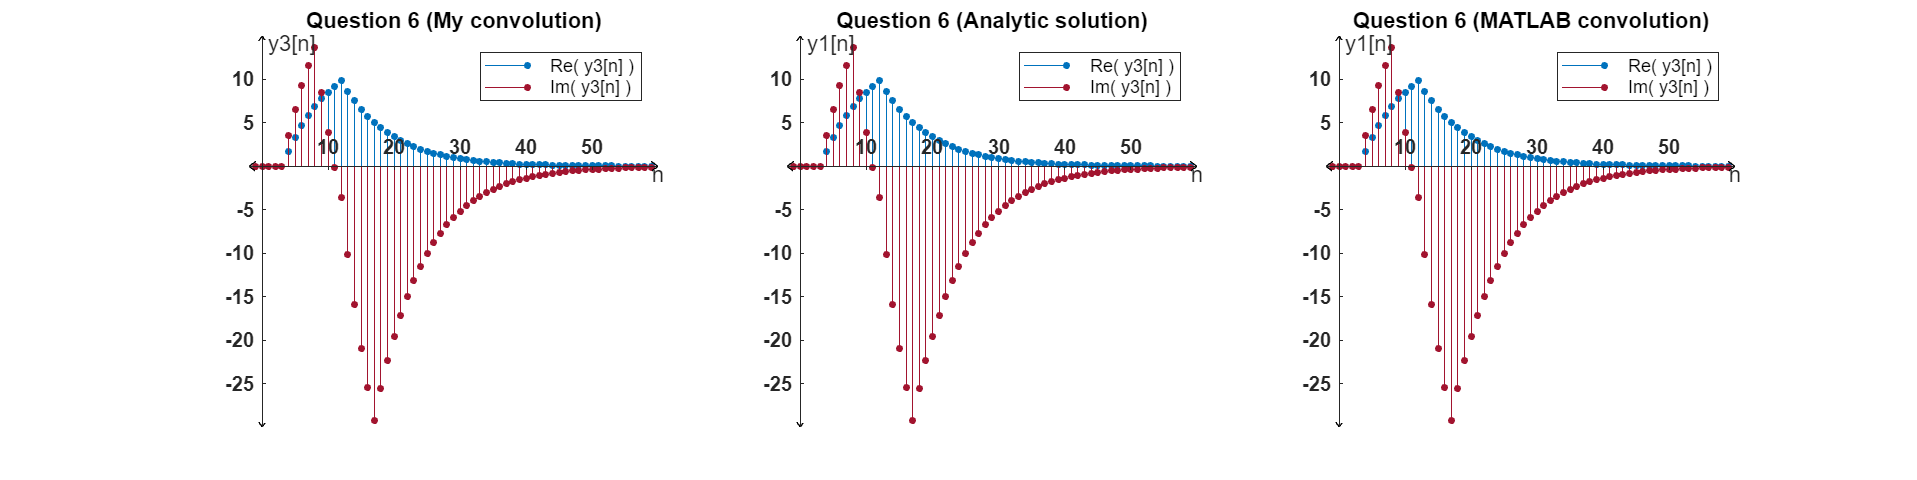

y6 = [y1 0 0 0 0 0] + 2j*y2; %we use zero padding for y1 to match sizes with y2
y6a = [y1a 0 0 0 0 0] + 2j*y2a;
n = linspace(-100,length(y6)-101,length(y6));

subplot(1,3,1)
finestem(n,real(y6),'Question 6 (My convolution)','n','y3[n]',[-2 60],[-30 15],'on',[1600 400])
finestem(n,imag(y6),'Question 6 (My convolution)','n','y3[n]',[-2 60],[-30 15],'off',[1600 400])
legend('Re( y3[n] )','','','','','','Im( y3[n] )') 
subplot(1,3,2)
finestem(n,real(y6a),'Question 6 (Analytic solution)','n','y1[n]',[-2 60],[-30 15],'on',[1600 400])
finestem(n,imag(y6a),'Question 6 (Analytic solution)','n','y1[n]',[-2 60],[-30 15],'off',[1600 400])
legend('Re( y3[n] )','','','','','','Im( y3[n] )')  
subplot(1,3,3)
finestem(n,real(conv(([x1 0 0 0 0 0]+2j*x2),h)),'Question 6 (MATLAB convolution)','n','y1[n]',[-2 60],[-30 15],'on',[1600 400])
finestem(n,imag(conv([x1 0 0 0 0 0]+2j*x2,h)),'Question 6 (MATLAB convolution)','n','y1[n]',[-2 60],[-30 15],'off',[1600 400])
legend('Re( y3[n] )','','','','','','Im( y3[n] )')  

We can see all of the plots for this question are identical. Therefore, we can say that my analytical solution and my convolution functions were correct.

# Functions Used:

##     Question 1 Analytical Solution:

function y = q1(n)
    if n < 4
        y = 0;
    elseif n > 12
        y = q1(12)*((7/8)^(n-12)); %using recursion for n = 12
    else
        y = 0;
        for i = linspace(4,n,n-3)
            y = y + (7/8)^(i);
        end
        y = y*3;
    end
end

##     Question 3 Analytical Solution:

function y = q3(n)
    if n < 6
        y = 0;
    elseif n > 24
        y = q3(24)*((7/8)^(n-24));
    else
        base = (7*exp(-1j/3))/8;
        sum1 = (1 - (base^(n-1)))/(1-base);
        sum2 = (1-(base^4))/(1-base);
        y = (sum1-sum2) * exp(n*1j/3);
    end
end

##     Unit Step    | Function:

function un = u(n)
    if n < 0
        un = 0;
    else
        un = 1;
    end
end 

##     convolution | Function:

function y = convolution(x,h);
    y = zeros([0 length(h)]); %initial size is the same as impulse function
    y = [y 0]; %extend size of result array to be compatible
    for i = x;
        y = y + i*h; % add the weighted impulse responses to the result
        h = [0 h]; %shift impulse function for the next operation
        y = [y 0]; %extend size of result array to be compatible
    end
end

##      finestem | Function:

The stem plotting function with other configurations to get the same style as the book:

- titlename,xaxisname,yaxisname all take string values that determine the corresponding text.

- xlimits,ylimits take 1x2 arrays that hold the limits of the plot in arbitrary order

- holdstate should take holdstate = 'off' as an input if you don't want to plot to be held any other input will not hold the plot

function finestem(n,x,titlename,xaxisname,yaxisname,xlimits,ylimits,holdstate,size)
    %even if the limits are reverse this section corrects the order
    if ylimits(1) > ylimits(2)
        ylimits = [ylimits(2) ylimits(1)];
    end
    if xlimits(1) > xlimits(2)
        xlimits = [xlimits(2) xlimits(1)];
    end

    %these measures are necessary for positioning arrows, labels etc. 
    dx = (xlimits(2)-xlimits(1))/65;
    dy = (ylimits(2)-ylimits(1))/85;

    %this section is to not plot values that overlap with the arrows
    lowindex = n(1);
    highindex = n(1);
    for i = n   
        if (i > xlimits(1) + dx) * (lowindex == n(1))
            lowindex = find(n==i);
        end
        if (i > xlimits(2) - dx) * (highindex == n(1))
            highindex = find(n==i)-1;
        end
    end
    if n(lowindex) > 0 %we allow points to be drawn at the origin
        lowindex = lowindex - 1;
    end
    if n(highindex) < 0 %we allow points to be drawn at the origin
        highindex = highindex + 1;
    end
    n = n(lowindex:highindex);
    x = x(lowindex:highindex);

    %this section is responsible for axis configuration
    stem(n,x,'filled','MarkerSize',3)
    xlim(xlimits)
    ylim(ylimits)
    set(get(gca,'XLabel'),'Visible','on')
    set(gca,'XAxisLocation','origin', 'box','off')
    set(gca,'YAxisLocation','origin')
    set(get(gca, 'XAxis'), 'FontWeight', 'bold')
    set(get(gca, 'YAxis'), 'FontWeight', 'bold');
    set(get(gca,'YLabel'),'Visible','on')
    set(gca,'Layer','top')
    set(gcf,'position',[(xlimits(2)-xlimits(1))/2 , (ylimits(2)-ylimits(1))/2 , size(1) , size(2)])
    
    %deletes the ticks that overlap with arrows
    xticks('auto');
    xt = xticks;
    xticks(xt(2:length(xt)-1));
    yticks('auto');
    yt = yticks;
    yticks(yt(2:length(yt)-1));
    
    % determining the ylevel to draw the arrows on the x axis
    if ((ylimits(1) * ylimits(2)) < 0) 
        xal = 0;
    elseif ylimits(1) < 0
        xal = ylimits(2);
    else
        xal = ylimits(1);
    end

    %plotting the arrows
    hold on
    if xlimits(2) > 0
        plot([(xlimits(2)-dx) xlimits(2) (xlimits(2)-dx)],[xal+dy xal xal-dy],'k') %xaxis right arrow 
    end
    if xlimits(1) < 0
        plot([xlimits(1)+dx xlimits(1) xlimits(1)+dx],[xal+dy xal xal-dy],'k') %xaxis left arrow 
    end 
    plot([0 0],[ylimits(2) ylimits(1)],'k')% y axis
    if ylimits(2) > 0 
        plot([-dx/2 0 dx/2],[ylimits(2)-dy ylimits(2) ylimits(2)-dy],'k') %yaxis top arrow 
    end
    if ylimits(1) < 0
        plot([-dx/2 0 dx/2],[ylimits(1)+dy ylimits(1) ylimits(1)+dy],'k') %yaxis bottom arrow 
    end
    
    %repositioning title & label locations
    label_h1 = xlabel(xaxisname);
    label_h1.Position(1) = xlimits(2)+dx; % change horizontal position of xlabel.
    label_h1.Position(2) = dy; % change vertical position of xlabel.c5
    label_h2 = ylabel(yaxisname,rotation=0);
    label_h2.Position(1) = dx; % change horizontal position of ylabel.
    label_h2.Position(2) = ylimits(2)+dy; % change vertical position of ylabel.
    title(titlename);
    if ((xlimits(1) * xlimits(2)) < 0) && (xlimits(1)+xlimits(2) < ((xlimits(2)-xlimits(1))/3))
        set(get(gca,'title'),'Position', [20*dx ylimits(2)-dy]) %prevents the title from colliding with ylabel
    end

    %holds or doesnt hold
    if strcmp(holdstate,'off')
        hold off
    else 
        hold on
    end
end